%This livescript intend to visualize the sampling of the tstat and ß
%images. The script works with the output of the sampling function
%BK_layer_sampling_pain_study_pipeline (see the function how to call)


plotidx=0;
allsubj={7349, 7356, 7361, 7375, 7376,...
         7383, 7402, 7403, 7404,...
         7405, 7408, 7414, 7415,...
         7425, 7426, 7433, 7434,...
         7435, 7443, 7444, 7445,...
         7448, 7449, 7452, 7453,...
         7454, 7455, 7456, 7457,...
         7468, 7469, 7482, 7484, 7485}; %34subj 7349 output was too big-->not safed and need to rerun, and 7356 has no good orientation was not run at all.32 is visualized now
% subjready={7403,7404,7444, 7484}
% subjready={7375, 7361, 7376,7383, 7402, 7403, 7404,7405, 7408, 7414, 7415};
subplotsize=[8 4];
% disp('This is the distribution of the indiviudal T value(across columns) for the three contrast')
allsubjlayer={};
subjidx=0;
td=[];
bu=[];
topdown=cell(2,1);
bottomup=cell(2,1);
for subj=allsubj%{7414,7482,7484,7485}
    roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
    processedimgfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls_DLPFCderived.mat'];
    %it has the follwoing output:
    %{1,1} cell: 2 cells, each for one side(left+right): vertex*image of the "columnarvalue"(deeper 75% of the column mean) 
    %{1,2} cell: 2 cells, each for one side(left+right): vertex*layer*image of the laminar value
    %{1,3} cell: 2 cells,each for one side(left+right): the depth of each "column"
    %{1,4} cell: the list of sampled images 
    if exist(processedimgfile,"file")
        processedimg=load(processedimgfile);
%         [columnspecificts,layeractivation,allroicolumnsize,sampled_img_list]
        disp([num2str(subj{:}) ' subject columnar info r'])
        nROI=length(processedimg.interimdata_columns{1,1});
        tthrs=1;
        topcolumnnumber=200; %200 or 100?
        subjidx=subjidx+1;
        plotidx=plotidx+1;
        allsubjid(plotidx)=subj{:};
        for ROI=1:nROI
            %based on t value
            conjugationcolumnarstat=min([processedimg.interimdata_columns{1,1}{ROI,1}(:,3),processedimg.interimdata_columns{1,1}{ROI,1}(:,4)],[],2); %3-cognition but need to be reversed!!,4-pain
            %based on ßmap
%             conjugationcolumnarstat=min([processedimg.interimdata_columns{1,1}{ROI,1}(:,1),processedimg.interimdata_columns{1,1}{ROI,1}(:,2)],[],2); %3-cognition but need to be reversed!!,4-pain
            
            
            numberofcolumnsinmask=length(conjugationcolumnarstat);
                    
            numberofactcolumnsbasedonconj=sum(conjugationcolumnarstat>tthrs);
                    
            disp(['Subject:' subj{:} 'The number of columns within the funcitonal mask: ',num2str(numberofcolumnsinmask)])
            
            disp(['Subject:' subj{:} 'The number of columns acitvating in each run(t>', num2str(tthrs), ') for cognition AND pain: ',num2str(numberofactcolumnsbasedonconj)])

            [top200Values, top200Indices] =maxk(conjugationcolumnarstat,topcolumnnumber);
            positiveIndices = top200Indices(top200Values > 0);
            % Check if any negative values were removed
            if length(positiveIndices) < topcolumnnumber
                warning('The top 200 values contained negative numbers. Only %d positive values are retained.', length(positiveIndices));
            end

            %this might be changed to the median, as that was used by Gao et al.
            subj_td=mean(processedimg.interimdata_columns{1,2}{ROI,1}(positiveIndices,:,1),1,'omitnan');%main effect of cognition but need to be reversed!!!;

            subj_bu=mean(processedimg.interimdata_columns{1,2}{ROI,1}(positiveIndices,:,2),1,'omitnan'); %main effect of pain
            %median
%             subj_td=median(processedimg.interimdata_columns{1,2}{ROI,1}(positiveIndices,:,1),1,'omitnan');%main effect of cognition, no reverstion in the DLPFCbut need to be reversed!!!;
% 
%             subj_bu=median(processedimg.interimdata_columns{1,2}{ROI,1}(positiveIndices,:,2),1,'omitnan'); %main effect of pain

            
            topdown{ROI}=vertcat(topdown{ROI},subj_td);
%             td=topdown{ROI};
            bottomup{ROI}=vertcat(bottomup{ROI},subj_bu);
%             bu=bottomup{ROI};
        end 
    else
        disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    end

end

7349 subject has  no sampled cluster
7356 subject has  no sampled cluster


7361 subject columnar info r


Subject:᳁The number of columns within the funcitonal mask: 5388


Subject:᳁The number of columns acitvating in each run(t>1) for cognition AND pain: 204


Subject:᳁The number of columns within the funcitonal mask: 1824


Subject:᳁The number of columns acitvating in each run(t>1) for cognition AND pain: 67


7375 subject columnar info r


Subject:᳏The number of columns within the funcitonal mask: 5653


Subject:᳏The number of columns acitvating in each run(t>1) for cognition AND pain: 35


Subject:᳏The number of columns within the funcitonal mask: 1856


Subject:᳏The number of columns acitvating in each run(t>1) for cognition AND pain: 3


7376 subject columnar info r


Subject:᳐The number of columns within the funcitonal mask: 6915


Subject:᳐The number of columns acitvating in each run(t>1) for cognition AND pain: 81


Subject:᳐The number of columns within the funcitonal mask: 2773


Subject:᳐The number of columns acitvating in each run(t>1) for cognition AND pain: 52


7383 subject columnar info r


Subject:᳗The number of columns within the funcitonal mask: 4819


Subject:᳗The number of columns acitvating in each run(t>1) for cognition AND pain: 155


Subject:᳗The number of columns within the funcitonal mask: 1590


Subject:᳗The number of columns acitvating in each run(t>1) for cognition AND pain: 83


7402 subject columnar info r


Subject:ᳪThe number of columns within the funcitonal mask: 11421


Subject:ᳪThe number of columns acitvating in each run(t>1) for cognition AND pain: 77


Subject:ᳪThe number of columns within the funcitonal mask: 4025


Subject:ᳪThe number of columns acitvating in each run(t>1) for cognition AND pain: 55


7403 subject columnar info r


Subject:ᳫThe number of columns within the funcitonal mask: 4995


Subject:ᳫThe number of columns acitvating in each run(t>1) for cognition AND pain: 38


Subject:ᳫThe number of columns within the funcitonal mask: 1521


Subject:ᳫThe number of columns acitvating in each run(t>1) for cognition AND pain: 9


7404 subject columnar info r


Subject:ᳬThe number of columns within the funcitonal mask: 4342


Subject:ᳬThe number of columns acitvating in each run(t>1) for cognition AND pain: 25


Subject:ᳬThe number of columns within the funcitonal mask: 1947


Subject:ᳬThe number of columns acitvating in each run(t>1) for cognition AND pain: 9


7405 subject columnar info r


Subject:᳭The number of columns within the funcitonal mask: 4378


Subject:᳭The number of columns acitvating in each run(t>1) for cognition AND pain: 49


Subject:᳭The number of columns within the funcitonal mask: 1435


Subject:᳭The number of columns acitvating in each run(t>1) for cognition AND pain: 11


7408 subject columnar info r


Subject:ᳰThe number of columns within the funcitonal mask: 6467


Subject:ᳰThe number of columns acitvating in each run(t>1) for cognition AND pain: 86


Subject:ᳰThe number of columns within the funcitonal mask: 2600


Subject:ᳰThe number of columns acitvating in each run(t>1) for cognition AND pain: 66


7414 subject columnar info r


Subject:ᳶThe number of columns within the funcitonal mask: 4798


Subject:ᳶThe number of columns acitvating in each run(t>1) for cognition AND pain: 36


Subject:ᳶThe number of columns within the funcitonal mask: 1692


Subject:ᳶThe number of columns acitvating in each run(t>1) for cognition AND pain: 6


7415 subject columnar info r


Subject:᳷The number of columns within the funcitonal mask: 5472


Subject:᳷The number of columns acitvating in each run(t>1) for cognition AND pain: 53


Subject:᳷The number of columns within the funcitonal mask: 1799


Subject:᳷The number of columns acitvating in each run(t>1) for cognition AND pain: 15


7425 subject columnar info r


Subject:ᴁThe number of columns within the funcitonal mask: 6369


Subject:ᴁThe number of columns acitvating in each run(t>1) for cognition AND pain: 54


Subject:ᴁThe number of columns within the funcitonal mask: 2079


Subject:ᴁThe number of columns acitvating in each run(t>1) for cognition AND pain: 13


7426 subject columnar info r


Subject:ᴂThe number of columns within the funcitonal mask: 4113


Subject:ᴂThe number of columns acitvating in each run(t>1) for cognition AND pain: 33


Subject:ᴂThe number of columns within the funcitonal mask: 1568


Subject:ᴂThe number of columns acitvating in each run(t>1) for cognition AND pain: 16


7433 subject columnar info r


Subject:ᴉThe number of columns within the funcitonal mask: 5420


Subject:ᴉThe number of columns acitvating in each run(t>1) for cognition AND pain: 67


Subject:ᴉThe number of columns within the funcitonal mask: 1936


Subject:ᴉThe number of columns acitvating in each run(t>1) for cognition AND pain: 25


7434 subject columnar info r


Subject:ᴊThe number of columns within the funcitonal mask: 5295


Subject:ᴊThe number of columns acitvating in each run(t>1) for cognition AND pain: 53


Subject:ᴊThe number of columns within the funcitonal mask: 1587


Subject:ᴊThe number of columns acitvating in each run(t>1) for cognition AND pain: 7


7435 subject columnar info r


Subject:ᴋThe number of columns within the funcitonal mask: 3968


Subject:ᴋThe number of columns acitvating in each run(t>1) for cognition AND pain: 85


Subject:ᴋThe number of columns within the funcitonal mask: 1308


Subject:ᴋThe number of columns acitvating in each run(t>1) for cognition AND pain: 36


7443 subject columnar info r


Subject:ᴓThe number of columns within the funcitonal mask: 6912


Subject:ᴓThe number of columns acitvating in each run(t>1) for cognition AND pain: 31


Subject:ᴓThe number of columns within the funcitonal mask: 2229


Subject:ᴓThe number of columns acitvating in each run(t>1) for cognition AND pain: 4


7444 subject columnar info r


Subject:ᴔThe number of columns within the funcitonal mask: 6684


Subject:ᴔThe number of columns acitvating in each run(t>1) for cognition AND pain: 85


Subject:ᴔThe number of columns within the funcitonal mask: 1885


Subject:ᴔThe number of columns acitvating in each run(t>1) for cognition AND pain: 21


7445 subject columnar info r


Subject:ᴕThe number of columns within the funcitonal mask: 6463


Subject:ᴕThe number of columns acitvating in each run(t>1) for cognition AND pain: 85


Subject:ᴕThe number of columns within the funcitonal mask: 1948


Subject:ᴕThe number of columns acitvating in each run(t>1) for cognition AND pain: 30


7448 subject columnar info r


Subject:ᴘThe number of columns within the funcitonal mask: 4021


Subject:ᴘThe number of columns acitvating in each run(t>1) for cognition AND pain: 37


Subject:ᴘThe number of columns within the funcitonal mask: 1892


Subject:ᴘThe number of columns acitvating in each run(t>1) for cognition AND pain: 16


7449 subject columnar info r


Subject:ᴙThe number of columns within the funcitonal mask: 5544


Subject:ᴙThe number of columns acitvating in each run(t>1) for cognition AND pain: 102


Subject:ᴙThe number of columns within the funcitonal mask: 1650


Subject:ᴙThe number of columns acitvating in each run(t>1) for cognition AND pain: 31


7452 subject columnar info r


Subject:ᴜThe number of columns within the funcitonal mask: 5881


Subject:ᴜThe number of columns acitvating in each run(t>1) for cognition AND pain: 86


Subject:ᴜThe number of columns within the funcitonal mask: 1831


Subject:ᴜThe number of columns acitvating in each run(t>1) for cognition AND pain: 43


7453 subject columnar info r


Subject:ᴝThe number of columns within the funcitonal mask: 5108


Subject:ᴝThe number of columns acitvating in each run(t>1) for cognition AND pain: 75


Subject:ᴝThe number of columns within the funcitonal mask: 1893


Subject:ᴝThe number of columns acitvating in each run(t>1) for cognition AND pain: 31


7454 subject columnar info r


Subject:ᴞThe number of columns within the funcitonal mask: 5257


Subject:ᴞThe number of columns acitvating in each run(t>1) for cognition AND pain: 264


Subject:ᴞThe number of columns within the funcitonal mask: 1407


Subject:ᴞThe number of columns acitvating in each run(t>1) for cognition AND pain: 51


7455 subject columnar info r


Subject:ᴟThe number of columns within the funcitonal mask: 5622


Subject:ᴟThe number of columns acitvating in each run(t>1) for cognition AND pain: 45


Subject:ᴟThe number of columns within the funcitonal mask: 1785


Subject:ᴟThe number of columns acitvating in each run(t>1) for cognition AND pain: 10


7456 subject columnar info r


Subject:ᴠThe number of columns within the funcitonal mask: 5142


Subject:ᴠThe number of columns acitvating in each run(t>1) for cognition AND pain: 168


Subject:ᴠThe number of columns within the funcitonal mask: 1711


Subject:ᴠThe number of columns acitvating in each run(t>1) for cognition AND pain: 52


7457 subject columnar info r


Subject:ᴡThe number of columns within the funcitonal mask: 6561


Subject:ᴡThe number of columns acitvating in each run(t>1) for cognition AND pain: 187


Subject:ᴡThe number of columns within the funcitonal mask: 2336


Subject:ᴡThe number of columns acitvating in each run(t>1) for cognition AND pain: 54


7468 subject columnar info r


Subject:ᴬThe number of columns within the funcitonal mask: 4247


Subject:ᴬThe number of columns acitvating in each run(t>1) for cognition AND pain: 117


Subject:ᴬThe number of columns within the funcitonal mask: 1969


Subject:ᴬThe number of columns acitvating in each run(t>1) for cognition AND pain: 49


7469 subject columnar info r


Subject:ᴭThe number of columns within the funcitonal mask: 4656


Subject:ᴭThe number of columns acitvating in each run(t>1) for cognition AND pain: 97


Subject:ᴭThe number of columns within the funcitonal mask: 1650


Subject:ᴭThe number of columns acitvating in each run(t>1) for cognition AND pain: 8


7482 subject columnar info r


Subject:ᴺThe number of columns within the funcitonal mask: 4339


Subject:ᴺThe number of columns acitvating in each run(t>1) for cognition AND pain: 60


Subject:ᴺThe number of columns within the funcitonal mask: 1541


Subject:ᴺThe number of columns acitvating in each run(t>1) for cognition AND pain: 41


7484 subject columnar info r


Subject:ᴼThe number of columns within the funcitonal mask: 4944


Subject:ᴼThe number of columns acitvating in each run(t>1) for cognition AND pain: 63


Subject:ᴼThe number of columns within the funcitonal mask: 1652


Subject:ᴼThe number of columns acitvating in each run(t>1) for cognition AND pain: 38


7485 subject columnar info r


Subject:ᴽThe number of columns within the funcitonal mask: 5223


Subject:ᴽThe number of columns acitvating in each run(t>1) for cognition AND pain: 34


Subject:ᴽThe number of columns within the funcitonal mask: 1814


Subject:ᴽThe number of columns acitvating in each run(t>1) for cognition AND pain: 25


nproc=2;
nsubj=length(allsubjid);
nside=1;

% td=array2table([topdown{1};topdown{2}],'VariableNames',strcat("layer",string(1:20)));
td=array2table([topdown{1}],'VariableNames',strcat("layer",string(1:20)));
td.process=repmat("topdown",nsubj*nside,1);
% td.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];
td.side=[repmat("right",nsubj,1)];

bu=array2table([bottomup{1}],'VariableNames',strcat("layer",string(1:20)));
bu.process=repmat("bottomup",nsubj*nside,1);
bu.side=[repmat("right",nsubj,1)];

s1=[td;bu];

s1.subjid=string(repmat(allsubjid',nproc*nside,1));
% s1.subjid=string(repmat(allsubjid',nproc,1));
pathtooutput='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\layerdata\';

writetable(s1,[ pathtooutput 'DLPFC_derived_layervalues.csv'])
% writematrix(allsubjid',[pathtooutput 'S1_subjid.csv'])


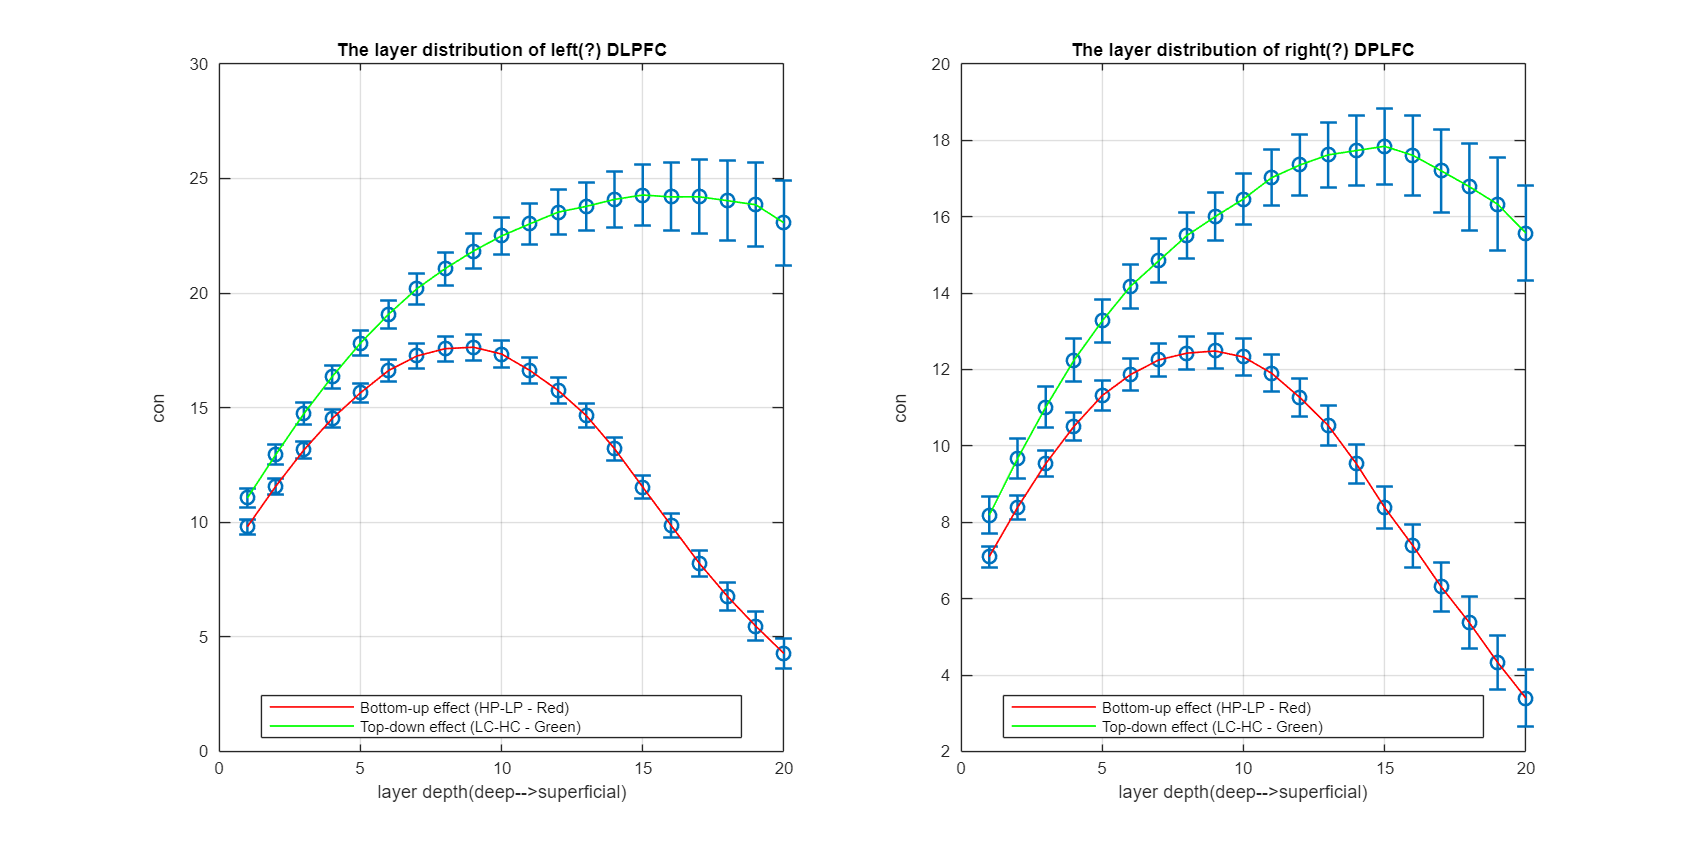

figure('Position',[100, 100, 2400, 1200]);

% alldataroi2_bet={bottomup_t,topdown_t};
for roitype=1:2
    alldata={bottomup{roitype,1}, topdown{roitype,1}};
    if roitype==1
    %             data=alldataroi1_beta{dataidx};
        titlenm='The layer distribution of left(?) DLPFC';
        
    elseif roitype==2
    %             data=alldataroi2_bet{dataidx};
        titlenm='The layer distribution of right(?) DPLFC';
        
    end
    for dataidx=1:2
        % Calculate column-wise mean and standard error

        data=alldata{dataidx};
        ylabltxt='con';
        columnMeans = mean(data, 1); % Mean of each column
        columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
        subplot(1,2,roitype)
        % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

        errorbar(1:20, columnMeans, columnStdErrors, ...
            'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
        hold on;
        
        % Connect the points with a line
        if dataidx==1
            lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
        else
            lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
        end

        % Customize the plot
        xlabel('layer depth(deep-->superficial)');
        ylabel(ylabltxt);
        % Add legend only for the lines
        
    %     label()
        title(titlenm);
        grid on;
        
    end
    legend([lineHandle1, lineHandle2], ...
        {'Bottom-up effect (HP-LP - Red)', ...
        'Top-down effect (LC-HC - Green)'}, ...
        'Location', 'south');
    hold off;
end